clear; close all; clc;
addpath('C:\femm42\mfiles');
openfemm;
opendocument('testDesign.fem');
mi_saveas('Test.fem'); 
mi_setgrid(1,'polar');

% Set zero current
mi_setcurrent('U', 0);
mi_setcurrent('V', 0);
mi_setcurrent('W', 0);

% Analyze and load solution
mi_analyze(1);
mi_loadsolution;

% Sample radial airgap field
L = 120;
rSample = 90.75; % mm
dAlpha_deg = 360 / L;
alpha_deg = (0:L-1) * dAlpha_deg;

Br = zeros(1, L);
for i = 1:L
    x = rSample * cosd(alpha_deg(i));
    y = rSample * sind(alpha_deg(i));
    B = mo_getb(x, y);
    Br(i) = B(1)*cosd(alpha_deg(i)) + B(2)*sind(alpha_deg(i));
end

mo_close;

## Problem 3

### Part (b)

Create a spectral plot of the airgap field harmonic components for this motor.

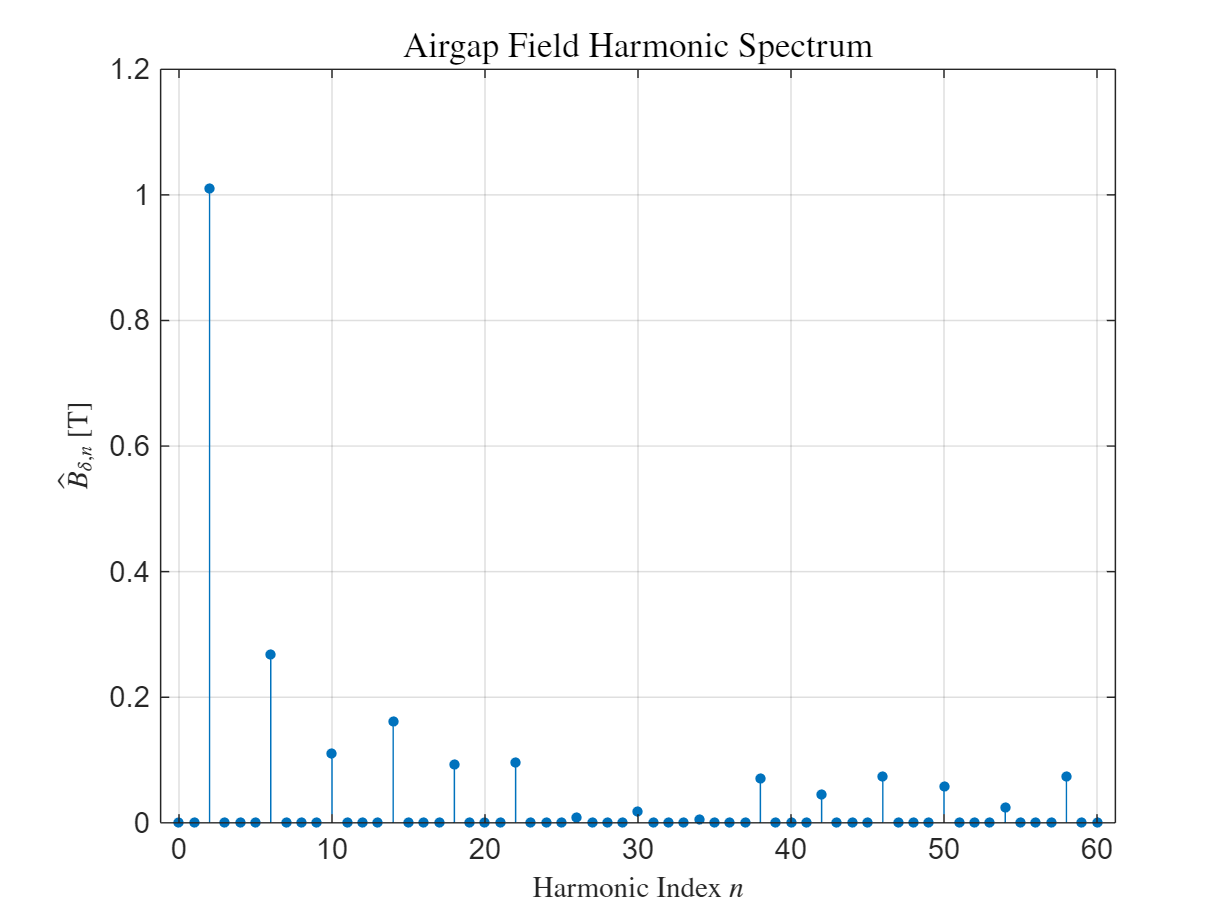

alpha_rad = deg2rad(alpha_deg);
Y = fft(Br);
P2 = abs(Y/L);
BrHarmonics = 2*P2(1:L/2+1);
n = 0:L/2;

% Plot spectrum (Part b)
figure;
stem(n, BrHarmonics, 'filled', 'MarkerSize', 3);
xlabel('Harmonic Index $n$', 'Interpreter','latex','FontSize',10);
ylabel('$\hat{B}_{\delta,n}$ [T]', 'Interpreter','latex','FontSize',10);
title('Airgap Field Harmonic Spectrum','Interpreter','latex','FontSize',12);
grid on;

### Part (c)

What is the magnetic loading of this motor?

fprintf('\nThe field contains the following harmonics:\n');


The field contains the following harmonics:


fprintf(' n | B_r,n [T]\n');

 n | B_r,n [T]


for i = 1:length(n)
    if BrHarmonics(i) > 0.01
        fprintf('%2.0f | %1.3f\n', n(i), BrHarmonics(i));
    end
end

 2 | 1.009
 6 | 0.268
10 | 0.110
14 | 0.161
18 | 0.092
22 | 0.096
30 | 0.019
38 | 0.070
42 | 0.045
46 | 0.074
50 | 0.057
54 | 0.024
58 | 0.074


% Magnetic Loading
magneticLoading = BrHarmonics(3);  % n=2 -> index = 3 (since n starts at 0)
fprintf('\nMagnetic loading (n=2): %.3f T\n', magneticLoading);


Magnetic loading (n=2): 1.009 T
